% Tensor Component Analysis (TCA): via Canonical Polyadic Decomposition (CPD)
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLT'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);


% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

function filtered_data = subtract_surrounding_channels(data, channel_locations)
    % Subtracts the mean of surrounding channels from each channel
    % 
    % Inputs:
    %   data: EEG data matrix (channels x time x trials)
    %   channel_locations: EEG.chanlocs structure containing channel coordinates
    %
    % Output:
    %   filtered_data: Data with surrounding channel mean subtracted
    
    num_channels = size(data, 1);
    num_timepoints = size(data, 2);
    num_trials = size(data, 3);
    filtered_data = zeros(size(data));
    
    % Extract coordinates for all channels
    if isfield(channel_locations, 'X') && isfield(channel_locations, 'Y') && isfield(channel_locations, 'Z')
        coords = [[channel_locations.X]', [channel_locations.Y]', [channel_locations.Z]'];
    else
        error('Channel locations must contain X, Y, and Z coordinates');
    end
    
    % Calculate Euclidean distances between all channels
    distances = zeros(num_channels, num_channels);
    for i = 1:num_channels
        for j = 1:num_channels
            distances(i,j) = sqrt(sum((coords(i,:) - coords(j,:)).^2));
        end
    end
    
    % Define surrounding channels for each channel
    % You can adjust the threshold to define what "surrounding" means
    threshold = mean(distances(:)) * 0.5; % Adjust this multiplier as needed
    
    for ch = 1:num_channels
        % Find surrounding channels (channels within threshold distance)
        surrounding_idx = find(distances(ch,:) > 0 & distances(ch,:) <= threshold);
        
        if isempty(surrounding_idx)
            warning(['No surrounding channels found for channel ', num2str(ch), '. Keeping original signal.']);
            filtered_data(ch,:,:) = data(ch,:,:);
            continue;
        end
        
        % Calculate mean of surrounding channels
        surrounding_mean = mean(data(surrounding_idx,:,:), 1);
        
        % Subtract surrounding mean from the channel
        filtered_data(ch,:,:) = data(ch,:,:) - surrounding_mean;
    end
end

% After loading and preprocessing your data (e.g., after bandpass filtering)
% Use your beta_signal variable
spatially_filtered_beta = subtract_surrounding_channels(beta_signal, EEG.chanlocs);

% Then continue with your analysis using spatially_filtered_beta instead of beta_signal

% TCA on pre-stimulus window
pre_data = spatially_filtered_beta(:, pre_idx,:); % ch x time x trial

%[U_pre,output_pre] = cpd(pre_data, 60);

% TCA on post-stimulus window
post_data = spatially_filtered_beta(:, post_idx,:); % ch x time x trial

%[U_post,output_post] = cpd(post_data, 60);

% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors_pre = zeros(size(num_components));
explained_variance_pre = zeros(size(num_components));
reconstruction_errors_post = zeros(size(num_components));
explained_variance_post = zeros(size(num_components));

if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end
parfor idx = 1:length(num_components)
    k = num_components(idx);

    [U_pre, ~] = cpd(pre_data, k, 'Display', 0);
    reconstructed_pre = cpdgen(U_pre);
    error_pre = norm(pre_data(:) - reconstructed_pre(:)) / norm(pre_data(:));
    reconstruction_errors_pre(idx) = error_pre;
    explained_variance_pre(idx) = 1 - error_pre^2;

    [U_post, ~] = cpd(post_data, k, 'Display', 0);
    reconstructed_post = cpdgen(U_post);
    error_post = norm(post_data(:) - reconstructed_post(:)) / norm(post_data(:));
    reconstruction_errors_post(idx) = error_post;
    explained_variance_post(idx) = 1 - error_post^2;
end


% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(2,2,1)
plot(num_components, reconstruction_errors_pre, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Pre stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,2)
plot(num_components, explained_variance_pre, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Pre stim vs. Number of Components');
grid on;

subplot(2,2,3)
plot(num_components, reconstruction_errors_post, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Post stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,4)
plot(num_components, explained_variance_post, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Post stim vs. Number of Components');
grid on;

threshold = 0.85;  % Target explained variance threshold

% Preallocate result
pc_at_85_pre = zeros(1, 1);
pc_at_85_post = zeros(1, 1);

pc_at_85_pre = find(round(explained_variance_pre,2) >= threshold, 1, 'first');
pc_at_85_post = find(round(explained_variance_post,2) >= threshold, 1, 'first'); 

% Marchenko-Pasture Test to see how many components are above random chance
% for pre and post-stimulus data across different dimensions

% Assume pre_data and post_data are 3D arrays: [channels × time_points × trials]
% Already extracted from beta_signal as in the draft script

%% Data dimensions
[channels_pre, time_points_pre, trials_pre] = size(pre_data);
[channels_post, time_points_post, trials_post] = size(post_data);

fprintf('Pre-stimulus data dimensions: %d channels, %d time points, %d trials\n', ...
    channels_pre, time_points_pre, trials_pre);

Pre-stimulus data dimensions: 32 channels, 204 time points, 60 trials


fprintf('Post-stimulus data dimensions: %d channels, %d time points, %d trials\n', ...
    channels_post, time_points_post, trials_post);

Post-stimulus data dimensions: 32 channels, 205 time points, 60 trials


% Run analysis on pre-stimulus data
[latent_chan_pre, lambda_max_chan_pre, lambda_min_chan_pre, n_sig_chan_pre, ...
 latent_time_pre, lambda_max_time_pre, lambda_min_time_pre, n_sig_time_pre, ...
 latent_trial_pre, lambda_max_trial_pre, lambda_min_trial_pre, n_sig_trial_pre] = ...
    run_mp_analysis(pre_data);

% Run analysis on post-stimulus data
[latent_chan_post, lambda_max_chan_post, lambda_min_chan_post, n_sig_chan_post, ...
 latent_time_post, lambda_max_time_post, lambda_min_time_post, n_sig_time_post, ...
 latent_trial_post, lambda_max_trial_post, lambda_min_trial_post, n_sig_trial_post] = ...
    run_mp_analysis(post_data);

% Print results
fprintf('\nPre-stimulus analysis results:\n');


Pre-stimulus analysis results:


fprintf('Channel mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_chan_pre, lambda_max_chan_pre);

Channel mode: 10 PCs exceed MP upper bound (λ_max = 1.1049).


fprintf('Time mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_time_pre, lambda_max_time_pre);

Time mode: 16 PCs exceed MP upper bound (λ_max = 1.7582).


fprintf('Trial mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_trial_pre, lambda_max_trial_pre);

Trial mode: 18 PCs exceed MP upper bound (λ_max = 1.2009).



fprintf('\nPost-stimulus analysis results:\n');


Post-stimulus analysis results:


fprintf('Channel mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_chan_post, lambda_max_chan_post);

Channel mode: 10 PCs exceed MP upper bound (λ_max = 1.1046).


fprintf('Time mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_time_post, lambda_max_time_post);

Time mode: 16 PCs exceed MP upper bound (λ_max = 1.7603).


fprintf('Trial mode: %d PCs exceed MP upper bound (λ_max = %.4f).\n', n_sig_trial_post, lambda_max_trial_post);

Trial mode: 18 PCs exceed MP upper bound (λ_max = 1.2004).


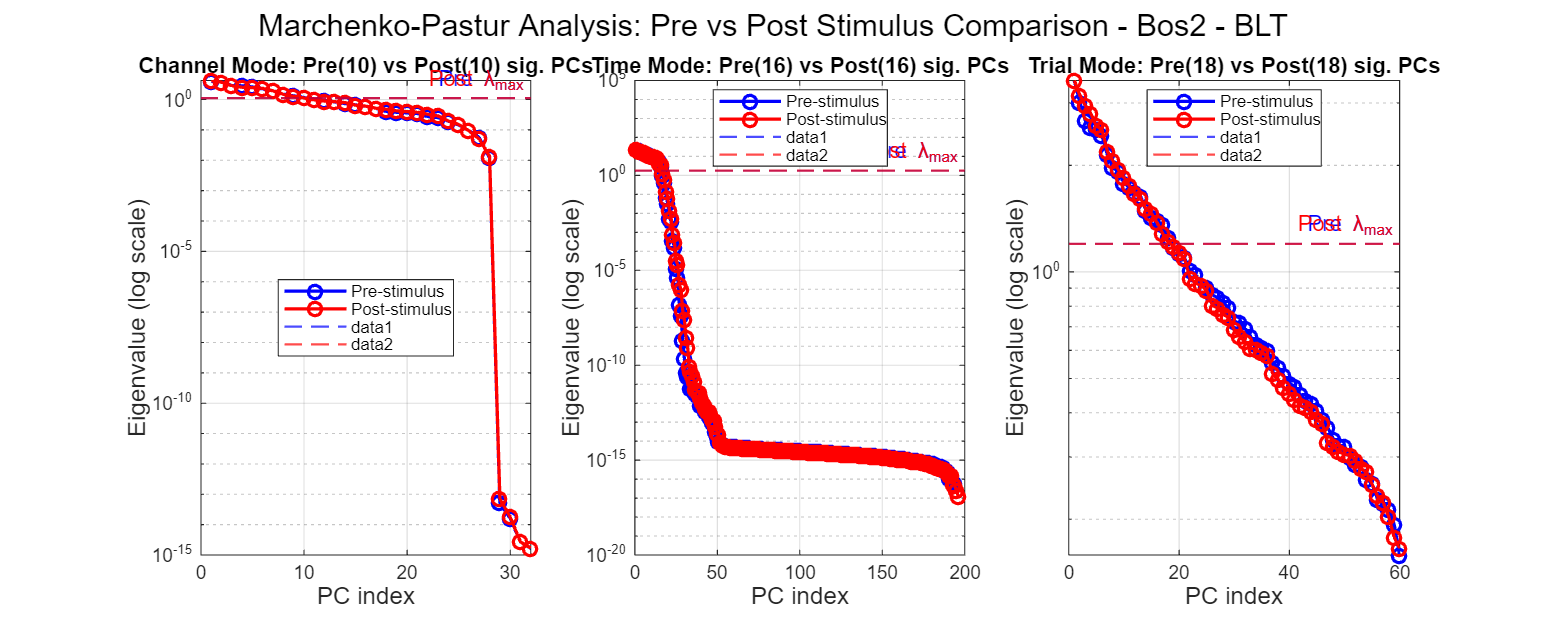


%% VISUALIZATIONS

% 1. Channel Mode Comparison
figure('Position', [100, 100, 1000, 400]);

% Channel mode - Pre vs Post
subplot(1, 3, 1);
semilogy(latent_chan_pre, 'bo-', 'LineWidth', 1.5, 'DisplayName', 'Pre-stimulus'); hold on;
semilogy(latent_chan_post, 'ro-', 'LineWidth', 1.5, 'DisplayName', 'Post-stimulus');
yline(lambda_max_chan_pre, 'b--', 'Pre λ_{max}', 'LineWidth', 1);
yline(lambda_max_chan_post, 'r--', 'Post λ_{max}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Channel Mode: Pre(%d) vs Post(%d) sig. PCs', n_sig_chan_pre, n_sig_chan_post), 'FontSize', 10);
legend('Location', 'best');
grid on;

% Time mode - Pre vs Post
subplot(1, 3, 2);
semilogy(latent_time_pre, 'bo-', 'LineWidth', 1.5, 'DisplayName', 'Pre-stimulus'); hold on;
semilogy(latent_time_post, 'ro-', 'LineWidth', 1.5, 'DisplayName', 'Post-stimulus');
yline(lambda_max_time_pre, 'b--', 'Pre λ_{max}', 'LineWidth', 1);
yline(lambda_max_time_post, 'r--', 'Post λ_{max}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Time Mode: Pre(%d) vs Post(%d) sig. PCs', n_sig_time_pre, n_sig_time_post), 'FontSize', 10);
legend('Location', 'best');
grid on;

% Trial mode - Pre vs Post
subplot(1, 3, 3);
semilogy(latent_trial_pre, 'bo-', 'LineWidth', 1.5, 'DisplayName', 'Pre-stimulus'); hold on;
semilogy(latent_trial_post, 'ro-', 'LineWidth', 1.5, 'DisplayName', 'Post-stimulus');
yline(lambda_max_trial_pre, 'b--', 'Pre λ_{max}', 'LineWidth', 1);
yline(lambda_max_trial_post, 'r--', 'Post λ_{max}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Trial Mode: Pre(%d) vs Post(%d) sig. PCs', n_sig_trial_pre, n_sig_trial_post), 'FontSize', 10);
legend('Location', 'best');
grid on;

sgtitle('Marchenko-Pastur Analysis: Pre vs Post Stimulus Comparison - Bos2 - BLT', 'FontSize', 14);

%% 2. Detailed Individual Plots - Pre-stimulus

% Pre-stimulus - All modes
figure('Position', [100, 500, 1000, 300]);

% Channel mode - Pre
subplot(1, 3, 1);
semilogy(latent_chan_pre, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_chan_pre, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_chan_pre, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Pre-stimulus: Channel Mode (%d sig. PCs)', n_sig_chan_pre), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

% Time mode - Pre
subplot(1, 3, 2);
semilogy(latent_time_pre, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_time_pre, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_time_pre, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Pre-stimulus: Time Mode (%d sig. PCs)', n_sig_time_pre), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

% Trial mode - Pre
subplot(1, 3, 3);
semilogy(latent_trial_pre, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_trial_pre, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_trial_pre, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Pre-stimulus: Trial Mode (%d sig. PCs)', n_sig_trial_pre), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

sgtitle('Marchenko-Pastur Analysis: Pre-stimulus Data', 'FontSize', 14);

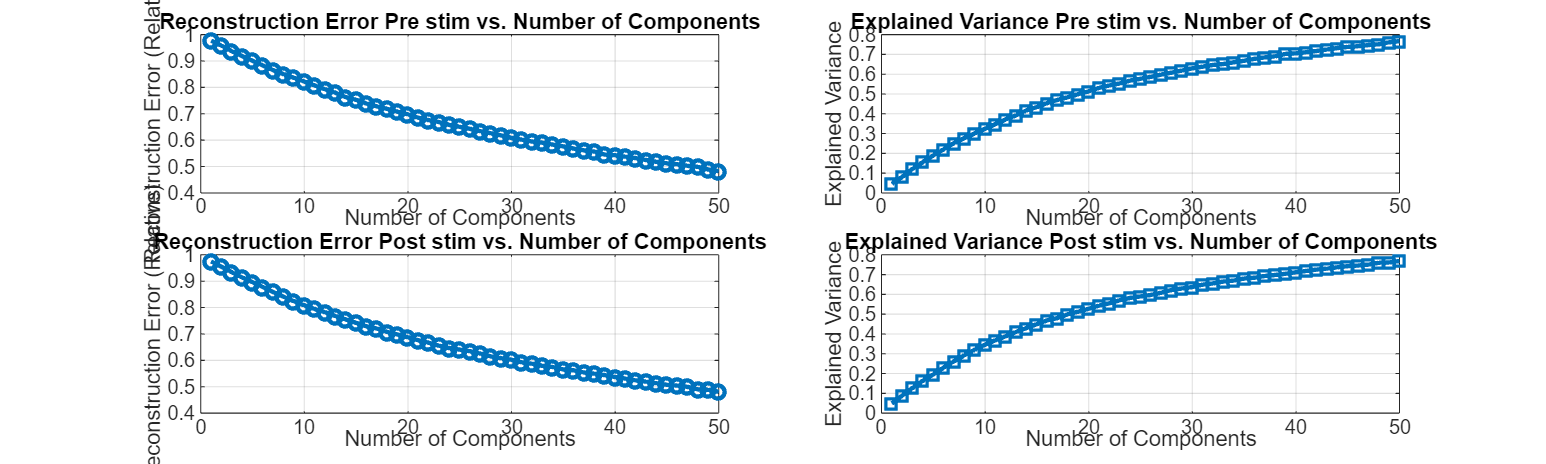


%% 3. Detailed Individual Plots - Post-stimulus

% Post-stimulus - All modes
figure('Position', [100, 900, 1000, 300]);

% Channel mode - Post
subplot(1, 3, 1);
semilogy(latent_chan_post, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_chan_post, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_chan_post, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Post-stimulus: Channel Mode (%d sig. PCs)', n_sig_chan_post), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

% Time mode - Post
subplot(1, 3, 2);
semilogy(latent_time_post, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_time_post, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_time_post, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Post-stimulus: Time Mode (%d sig. PCs)', n_sig_time_post), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

% Trial mode - Post
subplot(1, 3, 3);
semilogy(latent_trial_post, 'bo-', 'LineWidth', 1.5); hold on;
yline(lambda_max_trial_post, 'r--', '\lambda_{max}', 'LineWidth', 1);
yline(lambda_min_trial_post, 'b--', '\lambda_{min}', 'LineWidth', 1);
xlabel('PC index', 'FontSize', 11);
ylabel('Eigenvalue (log scale)', 'FontSize', 11);
title(sprintf('Post-stimulus: Trial Mode (%d sig. PCs)', n_sig_trial_post), 'FontSize', 10);
legend('Eigenvalues', '\lambda_{max}', '\lambda_{min}', 'Location', 'best');
grid on;

sgtitle('Marchenko-Pastur Analysis: Post-stimulus Data', 'FontSize', 14);

% Chosing to do TCA on the first 46 components since they explain 85% of
% the variance
[U_pre,output_pre ] = cpd(pre_data, pc_at_85_pre);

Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.

Error in cpd (line 210)
if ~exist('U','var') && R > 1


figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Neuron factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(U_pre{1}(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(pre_idx), U_pre{2}(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(U_pre{3}(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Pre-Stimulus)');


% Chosing to do TCA on the first 48 components since they explain 85% of
% the variance for post stimulus
[U_post,output_post ] = cpd(post_data, pc_at_85_post);

Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.

Error in cpd (line 210)
if ~exist('U','var') && R > 1

figure('Position', [100, 100, 1200, 1800]);  % Adjust size for vertical layout

for comp = 1:9
    row = comp;

    % Neuron factor (Column 1)
    subplot(9, 3, (row - 1)*3 + 1);
    bar(U_post{1}(:, comp));
    title(['Neuron - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    % Temporal factor (Column 2)
    subplot(9, 3, (row - 1)*3 + 2);
    plot(time_vector(post_idx), U_post{2}(:, comp), 'LineWidth', 2);
    title(['Temporal - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    % Trial factor (Column 3)
    subplot(9, 3, (row - 1)*3 + 3);
    stem(U_post{3}(:, comp), 'filled');
    title(['Trial - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end

sgtitle('Neuron, Temporal, and Trial Factor Loadings (Post-Stimulus)');

% Factor Analysis: The neuron factor correlation matrix

% Create correlation matrix for neural factor U_pre{1}
% Each column in U_pre{1} represents a component, so we compute correlations between components
correlation_matrix_pre = corrcoef(U_pre{1});

Undefined variable 'U_pre'.


% Plot the correlation matrix
figure('Position', [100, 100, 600, 500]);
imagesc(correlation_matrix_pre);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components pre-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_pre = size(correlation_matrix_pre, 1);
xticks(1:num_components_pre);
yticks(1:num_components_pre);

% If there are many components, you might want to show tick labels at intervals
if num_components_pre > 20
    xticks(1:5:num_components_pre);
    yticks(1:5:num_components_pre);
end
% Perform SVD on the correlation matrix of neural factors
% correlation_matrix_pre = corrcoef(U_pre{1});

% Apply SVD
[Un_pre, S_pre, V_pre] = svd(correlation_matrix_pre);

% Extract singular values (diagonal elements of S)
singular_values_pre = diag(S_pre);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Neural Factor Correlation Matrix - pre-stim');
grid on;

% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_pre), singular_values_pre, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Neural Factor Correlation Matrix (Log Scale) pre-stim');
grid on;

% Calculate cumulative explained variance
explained_variance_pre = singular_values_pre / sum(singular_values_pre);
cumulative_variance_pre = cumsum(explained_variance_pre);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_pre), cumulative_variance_pre, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 90% explained variance
yline(0.9, '--', '90% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD pre-stim');
grid on;

% Find number of components needed to explain 90% of variance
components_90pct_pre = find(cumulative_variance_pre >= 0.9, 1);
text(components_90pct_pre + 0.5, 0.9, ['\leftarrow ' num2str(components_90pct_pre) ' components'], 'FontSize', 12);
figure;
imagesc(V_pre(:,1:3)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Neural Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap');
set(gca, 'YTick', 1:3, 'YTickLabel', {'PC1', 'PC2', 'PC3'});
for i = 1:3  % For each of your top 3 components
    [sortedValues_pre, sortedIndices_pre] = sort(abs(V_pre(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_pre))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_pre(j), V_pre(sortedIndices_pre(j),i));
    end
    fprintf('\n');
end
% Assuming U_pre{1} is your original data matrix and U, S, V are from your SVD
componentScores_pre = U_pre{1} * V_pre(:,1:3);  % Project data onto first 3 components

% Calculate correlations between component scores and original factors
correlationMatrix_pre = corr(componentScores_pre, U_pre{1});

figure;
imagesc(correlationMatrix_pre');
colormap(jet);
colorbar;
xlabel('Principal Components');
ylabel('Neural Factors');
title('Correlation between Components and Factors');
set(gca, 'XTick', 1:3, 'XTickLabel', {'PC1', 'PC2', 'PC3'});

% Create correlation matrix for neural factor U_post{1}
% Each column in U_post{1} represents a component, so we compute correlations between components
correlation_matrix_post = corrcoef(U_post{1});

Undefined variable 'U_post'.


% Plot the correlation matrix
figure('Position', [100, 100, 600, 500]);
imagesc(correlation_matrix_post);
colormap('jet');
colorbar;
axis square;
title('Correlation Matrix of Neural Factor Components post-stimulus');
xlabel('Component');
ylabel('Component');

% Add component numbers to the tick labels
num_components_post = size(correlation_matrix_post, 1);
xticks(1:num_components_post);
yticks(1:num_components_post);

% If there are many components, you might want to show tick labels at intervals
if num_components_post > 20
    xticks(1:5:num_components_post);
    yticks(1:5:num_components_post);
end


% Perform SVD on the correlation matrix of neural factors
correlation_matrix_post = corrcoef(U_post{1});

% Apply SVD
[Un_post, S_post, V_post] = svd(correlation_matrix_post);

% Extract singular values (diagonal elements of S)
singular_values_post = diag(S_post);

% Plot singular values vs. rank
figure('Position', [100, 100, 600, 400]);
plot(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value');
title('Singular Values of Neural Factor Correlation Matrix - post-stim');
grid on;

% Add log-scale version (often useful for seeing trend across all values)
figure('Position', [100, 100, 600, 400]);
semilogy(1:length(singular_values_post), singular_values_post, 'o-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Rank');
ylabel('Singular Value (log scale)');
title('Singular Values of Neural Factor Correlation Matrix (Log Scale) post-stim');
grid on;

% Calculate cumulative explained variance
explained_variance_post = singular_values_post / sum(singular_values_post);
cumulative_variance_post = cumsum(explained_variance_post);

% Plot cumulative explained variance
figure('Position', [100, 100, 600, 400]);
plot(1:length(cumulative_variance_post), cumulative_variance_post, 's-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;
% Add horizontal line at 90% explained variance
yline(0.9, '--', '90% Explained Variance', 'LineWidth', 1.5);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance from SVD Post-stimulus');
grid on;

% Find number of components needed to explain 90% of variance
components_90pct_post = find(cumulative_variance_post >= 0.9, 1);
text(components_90pct_post + 0.5, 0.9, ['\leftarrow ' num2str(components_90pct_post) ' components'], 'FontSize', 12);
figure;
imagesc(V_post(:,1:3)');  % Transpose to get components as rows
colormap(jet);
colorbar;
xlabel('Neural Factors');
ylabel('Principal Components');
title('Component-Factor Loadings Heatmap');
set(gca, 'YTick', 1:3, 'YTickLabel', {'PC1', 'PC2', 'PC3'});
for i = 1:3  % For each of your top 3 components
    [sortedValues_post, sortedIndices_post] = sort(abs(V_post(:,i)), 'descend');
    fprintf('Principal Component %d - Top contributing factors:\n', i);
    for j = 1:min(10, length(sortedIndices_post))  % Show top 10 factors
        fprintf('  Factor %d: Loading = %.4f\n', sortedIndices_post(j), V_post(sortedIndices_post(j),i));
    end
    fprintf('\n');
end
% Assuming U_pre{1} is your original data matrix and U, S, V are from your SVD
componentScores_post = U_post{1} * V_post(:,1:3);  % Project data onto first 3 components

% Calculate correlations between component scores and original factors
correlationMatrix_post = corr(componentScores_post, U_post{1});

figure;
imagesc(correlationMatrix_post');
colormap(jet);
colorbar;
xlabel('Principal Components');
ylabel('Neural Factors');
title('Correlation between Components and Factors');
set(gca, 'XTick', 1:3, 'XTickLabel', {'PC1', 'PC2', 'PC3'});

% Temporal factor analysis: FFT
% FFT analysis on temporal factors with normalization

% Define parameters for FFT
sampling_rate = fs; % Use your original sampling rate from EEG data
time_pre = time_vector(pre_idx);
time_post = time_vector(post_idx);
dt_pre = mean(diff(time_pre)); % Time step for pre-stimulus
dt_post = mean(diff(time_post)); % Time step for post-stimulus

% Calculate frequency axis
N_pre = length(time_pre);
freq_pre = (0:N_pre-1)/(N_pre*dt_pre); % Frequency axis in Hz
freq_pre = freq_pre(1:floor(N_pre/2)+1); % Keep only positive frequencies

N_post = length(time_post);
freq_post = (0:N_post-1)/(N_post*dt_post); % Frequency axis in Hz
freq_post = freq_post(1:floor(N_post/2)+1); % Keep only positive frequencies

% Preallocate arrays to store power spectra for normalization
pre_power_spectra = zeros(length(freq_pre), 9);
post_power_spectra = zeros(length(freq_post), 9);

% Compute FFT for all pre-stimulus components
for comp = 1:9
    signal = U_pre{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_pre);
    P1 = P2(1:floor(N_pre/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    pre_power_spectra(:, comp) = P1;
end

Undefined variable 'U_pre'.


% Compute FFT for all post-stimulus components
for comp = 1:9
    signal = U_post{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_post);
    P1 = P2(1:floor(N_post/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    post_power_spectra(:, comp) = P1;
end

% Normalize each power spectrum by its maximum value
for comp = 1:9
    pre_power_spectra(:, comp) = pre_power_spectra(:, comp) / max(pre_power_spectra(:, comp));
    post_power_spectra(:, comp) = post_power_spectra(:, comp) / max(post_power_spectra(:, comp));
end

% Create figures for pre-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_pre, pre_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Pre-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_pre))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Pre-stimulus Temporal Factors (U\_pre{2})');

% Create figures for post-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_post, post_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Post-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_post))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Post-stimulus Temporal Factors (U\_post{2})');
% Systematic approach to selecting perplexity for temporal factors
perplexity_values = [5, 10, 12, 15, 20, 30];
num_dims = 2;  % Using 2D for easier comparison

% Prepare temporal factors
temporal_factors_pre = U_pre{2};  % Time points × components
temporal_factors_post = U_post{2};  % Time points × components

% Preallocate cell arrays to store results
Y_pre_temporal_results = cell(length(perplexity_values), 1);
Y_post_temporal_results = cell(length(perplexity_values), 1);

% Run t-SNE with different perplexity values
for i = 1:length(perplexity_values)
    perp = perplexity_values(i);
    
    % Pre-stimulus
    effective_perp_pre = min(perp, size(temporal_factors_pre, 1)-1);
    Y_pre_temporal_results{i} = tsne(temporal_factors_pre, 'Perplexity', effective_perp_pre, 'NumDimensions', num_dims);
    
    % Post-stimulus
    effective_perp_post = min(perp, size(temporal_factors_post, 1)-1);
    Y_post_temporal_results{i} = tsne(temporal_factors_post, 'Perplexity', effective_perp_post, 'NumDimensions', num_dims);
end

% Create a grid of plots for pre-stimulus temporal results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Color points by time
    scatter(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 30, time_vector(pre_idx), 'filled');
    title(['Pre-stimulus Temporal, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;
end
sgtitle('Effect of Perplexity on Pre-stimulus Temporal t-SNE Results');

% Create a grid of plots for post-stimulus temporal results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Color points by time
    scatter(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 30, time_vector(post_idx), 'filled');
    title(['Post-stimulus Temporal, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;
end
sgtitle('Effect of Perplexity on Post-stimulus Temporal t-SNE Results');

% Add trajectory plots for different perplexity values
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Plot points colored by time
    scatter(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 30, time_vector(pre_idx), 'filled');
    hold on;
    % Add connecting line to show trajectory
    plot(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 'k-', 'LineWidth', 1);
    title(['Pre-stimulus Trajectory, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
    hold off;
end
sgtitle('Temporal Trajectories for Different Perplexity Values (Pre-stimulus)');

% Same for post-stimulus trajectories
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 30, time_vector(post_idx), 'filled');
    hold on;
    plot(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 'k-', 'LineWidth', 1);
    title(['Post-stimulus Trajectory, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
    hold off;
end
sgtitle('Temporal Trajectories for Different Perplexity Values (Post-stimulus)');
% Parameters for t-SNE
perplexity = 10; % Default perplexity - adjust based on the number of time points
num_dims = 2;    % 2D visualization 

% t-SNE for pre-stimulus temporal factors
% Transpose so each row represents a time point, each column is a component
temporal_factors_pre = U_pre{2}; % Already in the right format (time points × components)
Y_pre_temporal = tsne(temporal_factors_pre, 'Perplexity', min(perplexity, size(temporal_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus temporal factors
temporal_factors_post = U_post{2}; % Already in the right format (time points × components)
Y_post_temporal = tsne(temporal_factors_post, 'Perplexity', min(perplexity, size(temporal_factors_post, 1)-1), 'NumDimensions', num_dims);

% Plot pre-stimulus temporal t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 50, time_vector(pre_idx), 'filled');
colormap(jet);
tick_vals_pre = [min(time_vector(pre_idx)), 0, max(time_vector(pre_idx))];
tick_vals_pre = unique(sort(tick_vals_pre)); % Ensure increasing and remove duplicates
tick_labels_pre = arrayfun(@(x) num2str(x, '%.2f'), tick_vals_pre, 'UniformOutput', false);
colorbar('Ticks', tick_vals_pre, 'TickLabels', tick_labels_pre);
title('t-SNE of Pre-stimulus Temporal Factors (U\_pre{2})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

% Plot post-stimulus temporal t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_post_temporal(:,1), Y_post_temporal(:,2), 50, time_vector(post_idx), 'filled');
colormap(jet);
tick_vals_post = [min(time_vector(post_idx)), 0, max(time_vector(post_idx))];
tick_vals_post = unique(sort(tick_vals_post)); % Ensure increasing and remove duplicates
tick_labels_post = arrayfun(@(x) num2str(x, '%.2f'), tick_vals_post, 'UniformOutput', false);
colorbar('Ticks', tick_vals_post, 'TickLabels', tick_labels_post);
title('t-SNE of Post-stimulus Temporal Factors (U\_post{2})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

% Add a version with labeled time points (useful for seeing temporal progression)
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 50, 'filled');
title('t-SNE of Pre-stimulus Temporal Factors with Time Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;

% Add time labels at selected intervals (to avoid overcrowding)
time_labels = time_vector(pre_idx);
interval = max(1, round(length(time_labels) / 10)); % Show ~10 labels
for i = 1:interval:length(time_labels)
    text(Y_pre_temporal(i,1), Y_pre_temporal(i,2), num2str(time_labels(i), '%.2f'), 'FontSize', 8);
end

% Add a version with labeled time points for post-stimulus
figure('Position', [100, 100, 800, 600]);
scatter(Y_post_temporal(:,1), Y_post_temporal(:,2), 50, 'filled');
title('t-SNE of Post-stimulus Temporal Factors with Time Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;

% Add time labels at selected intervals
time_labels = time_vector(post_idx);
interval = max(1, round(length(time_labels) / 10)); % Show ~10 labels
for i = 1:interval:length(time_labels)
    text(Y_post_temporal(i,1), Y_post_temporal(i,2), num2str(time_labels(i), '%.2f'), 'FontSize', 8);
end

% Alternative: Connect points with a line to show temporal trajectory
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 30, time_vector(pre_idx), 'filled');
hold on;
plot(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 'k-', 'LineWidth', 1);
colormap(jet);
colorbar;
title('Temporal Trajectory in Pre-stimulus t-SNE Space');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

figure('Position', [100, 100, 800, 600]);
scatter(Y_post_temporal(:,1), Y_post_temporal(:,2), 30, time_vector(post_idx), 'filled');
hold on;
plot(Y_post_temporal(:,1), Y_post_temporal(:,2), 'k-', 'LineWidth', 1);
colormap(jet);
colorbar;
title('Temporal Trajectory in Post-stimulus t-SNE Space');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

% Time factor analysis using UMAP
% First, make sure you have the UMAP MATLAB package installed
% You can install it via: 
% https://www.mathworks.com/matlabcentral/fileexchange/71902-uniform-manifold-approximation-and-projection-umap

% Define parameter combinations to test
% n_neighbors_values = [3, 8, 15, 20];
% min_dist_values = [0.1, 0.5, 0.8]; % Changed 1.0 to 0.8 to avoid potential boundary issues
n_neighbors_values = [3];
min_dist_values = [0.1]; %

% Number of combinations
num_combinations = length(n_neighbors_values) * length(min_dist_values);

% Create structure to store results
results = struct('n_neighbors', {}, 'min_dist', {}, ...
                'umap_time_pre', {}, 'umap_time_post', {}, ...
                'pre_clusters', {}, 'post_clusters', {}, ...
                'status', {});

% Set consistent random seed for reproducibility
rng(42);

% Prepare figure for visualization
figure('Position', [100, 100, 1200, 800]);

% Counter for subplot positions
combo_idx = 1;

% Loop through all parameter combinations
for i = 1:length(n_neighbors_values)
    for j = 1:length(min_dist_values)
        % Current parameter set
        curr_n_neighbors = n_neighbors_values(i);
        curr_min_dist = min_dist_values(j);
        
        % Initialize current result entry
        curr_result = struct('n_neighbors', curr_n_neighbors, ...
                           'min_dist', curr_min_dist, ...
                           'umap_time_pre', [], 'umap_time_post', [], ...
                           'pre_clusters', [], 'post_clusters', [], ...
                           'status', 'pending');
        
        % Display current parameter combination
        fprintf('Testing n_neighbors=%d, min_dist=%.2f (%d/%d)\n', ...
                curr_n_neighbors, curr_min_dist, num_combinations);
        
        % Try running UMAP with current parameters
        try
            % Run UMAP on pre-condition trial factors
            [umap_time_pre, umap_time_params] = run_umap(U_pre{2}, 'n_neighbors', curr_n_neighbors, ...
                                             'min_dist', curr_min_dist, ...
                                             'n_components', 2, ...
                                             'seed', 42);
            
            % Run UMAP on post-condition trial factors
            [umap_time_post, ~] = run_umap(U_post{2}, 'n_neighbors', curr_n_neighbors, ...
                                    'min_dist', curr_min_dist, ...
                                    'n_components', 2, ...
                                    'seed', 42);
            
            % Store UMAP results
            curr_result.umap_time_pre = umap_time_pre;
            curr_result.umap_time_post = umap_time_post;
            
            % Apply DBSCAN clustering
            epsilon = 0.5;  % You might want to adjust this for each parameter set
            minPts = 5;
            
            curr_result.pre_clusters = dbscan(umap_time_pre, epsilon, minPts);
            curr_result.post_clusters = dbscan(umap_time_post, epsilon, minPts);
            
            % Mark as successful
            curr_result.status = 'success';
            
           % Create a new figure for this parameter combination
            fig = figure('Position', [100, 100, 1000, 600]);
            
            % Pre-stimulus plot
            subplot(1, 2, 1);
            gscatter(umap_time_pre(:,1), umap_time_pre(:,2), curr_result.pre_clusters);
            title(sprintf('Pre-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Post-stimulus plot
            subplot(1, 2, 2);
            gscatter(umap_time_post(:,1), umap_time_post(:,2), curr_result.post_clusters);
            title(sprintf('Post-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Add overall title
            sgtitle(sprintf('UMAP Parameter Combination %d/%d: n\\_neighbors=%d, min\\_dist=%.2f', ...
                combo_idx, num_combinations, curr_n_neighbors, curr_min_dist));
            
            % % Save the figure
            % fig_filename = sprintf('umap_params_n%d_d%.2f.png', curr_n_neighbors, curr_min_dist);
            % saveas(fig, fig_filename);
            % 
            % % Optional: close the figure if you don't want too many open at once
            % close(fig);
            
        catch e
            % Handle errors
            fprintf('Error with n_neighbors=%d, min_dist=%.2f: %s\n', ...
                    curr_n_neighbors, curr_min_dist, e.message);
            curr_result.status = sprintf('error: %s', e.message);
        end
        
        % Store current result
        results(end+1) = curr_result;
        
        % Increment combination counter
        combo_idx = combo_idx + 1;
    end
end

Testing n_neighbors=3, min_dist=0.10 (1/

Error with n_neighbors=3, min_dist=0.10: Undefined variable 'U_pre'.



% Save all results to a MAT file
save('umap_time_parameter_exploration.mat', 'results');

% Display summary
fprintf('\nParameter Testing Summary:\n');


Parameter Testing Summary:


fprintf('------------------------\n');

------------------------


for i = 1:length(results)
    fprintf('n_neighbors=%d, min_dist=%.2f: %s\n', ...
            results(i).n_neighbors, results(i).min_dist, results(i).status);
end

n_neighbors=3, min_dist=0.10: error: Undefined variable 'U_pre'.


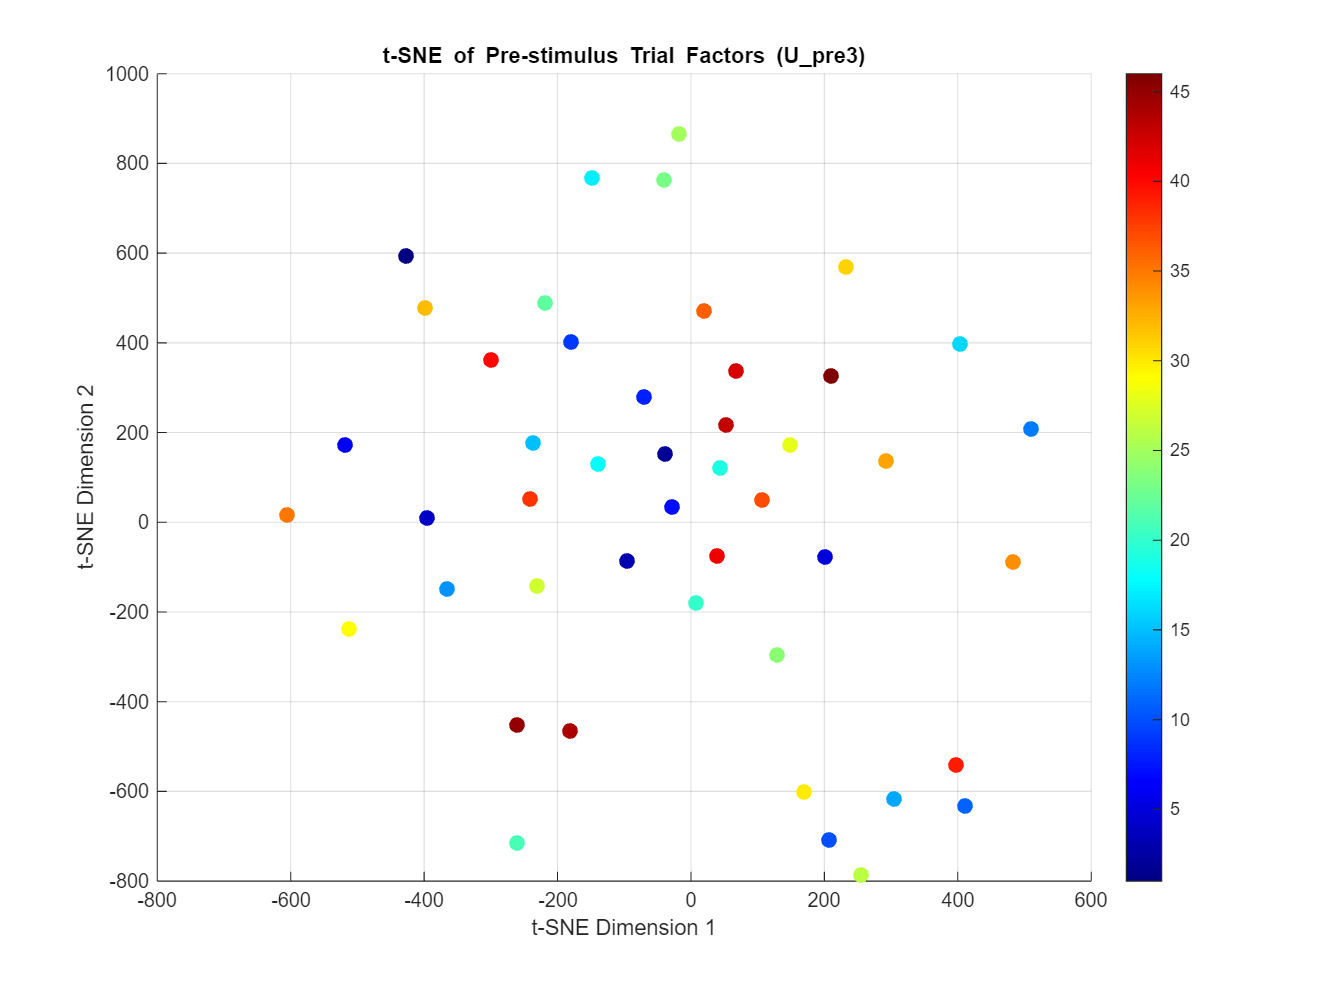

% Trial Factor analysis: t-SNE clustering

% t-SNE clustering on trial factors U_pre{3} and U_post{3}

% Parameters for t-SNE
perplexity = 10; % Default perplexity - adjust based on your number of trials, n/3, 60/3 =20
num_dims = 2;    % 2D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre_trial = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post_trial = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% Plot pre-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_trial(:,1), Y_pre_trial(:,2), 50, 1:size(Y_pre_trial,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Pre-stimulus Trial Factors (U\_pre{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

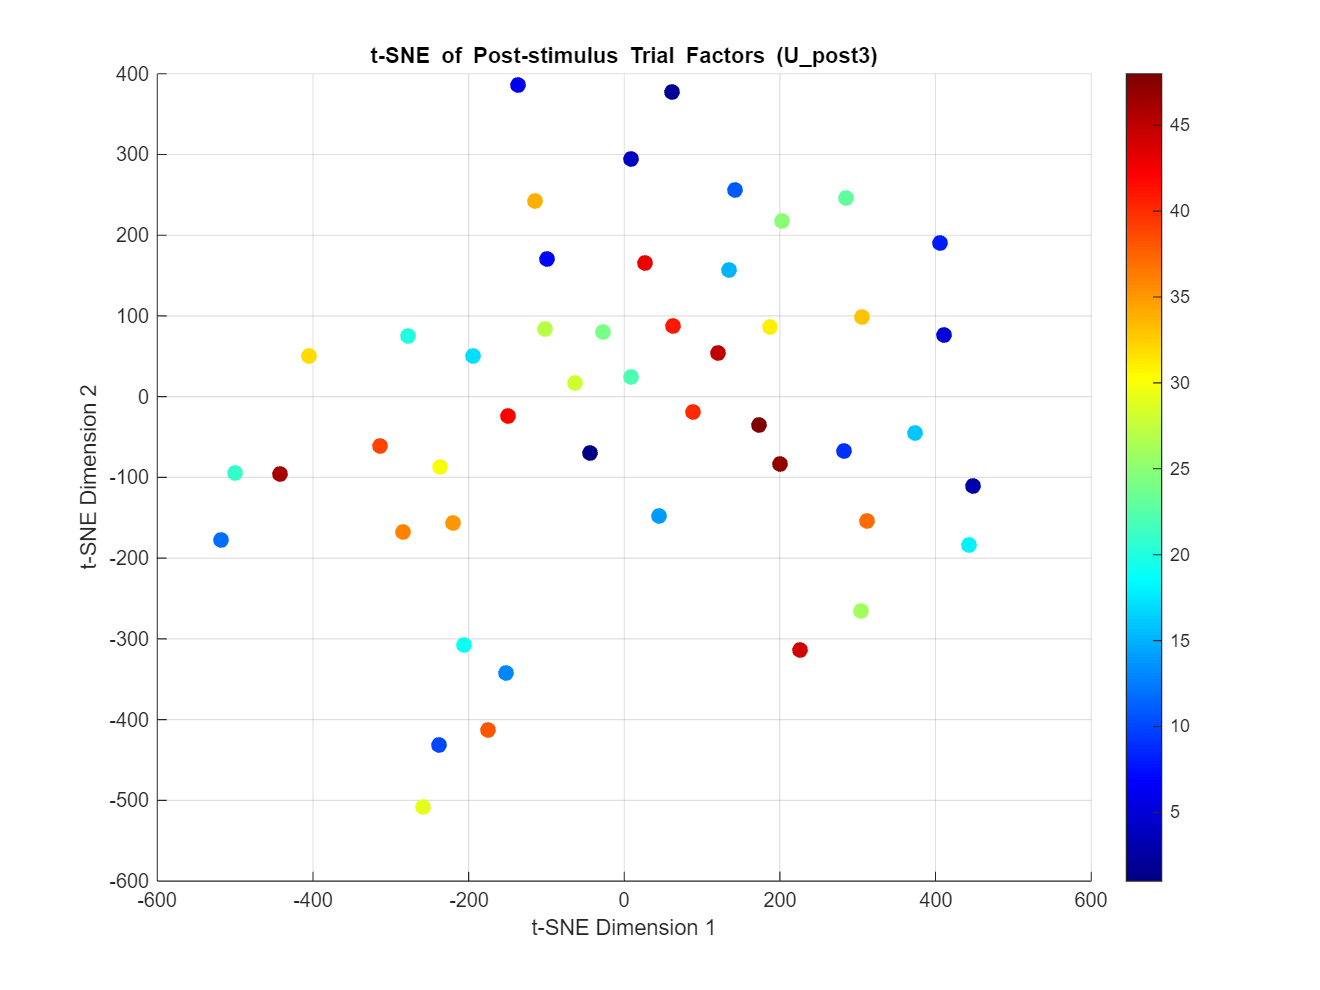


% Plot post-stimulus t-SNE results
figure('Position', [100, 100, 800, 600]);
scatter(Y_post_trial(:,1), Y_post_trial(:,2), 50, 1:size(Y_post_trial,1), 'filled');
colormap(jet);
colorbar;
title('t-SNE of Post-stimulus Trial Factors (U\_post{3})');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
grid on;

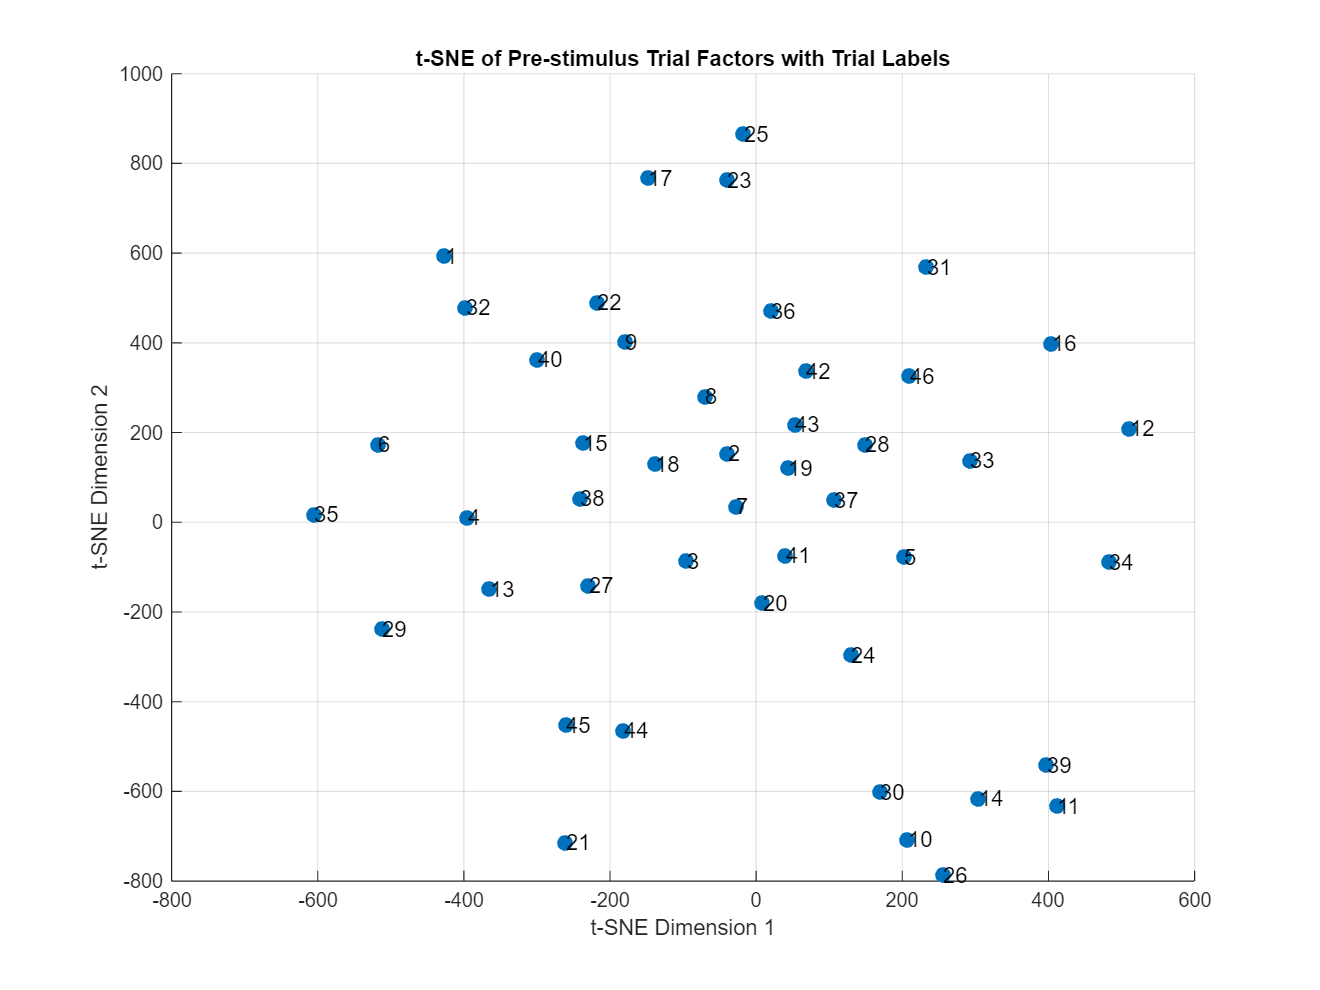


% Alternative visualization: Plot with trial numbers as labels
figure('Position', [100, 100, 800, 600]);
scatter(Y_pre_trial(:,1), Y_pre_trial(:,2), 50, 'filled');
title('t-SNE of Pre-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_pre_trial, 1)
    text(Y_pre_trial(i,1), Y_pre_trial(i,2), num2str(i), 'FontSize', 10);
end

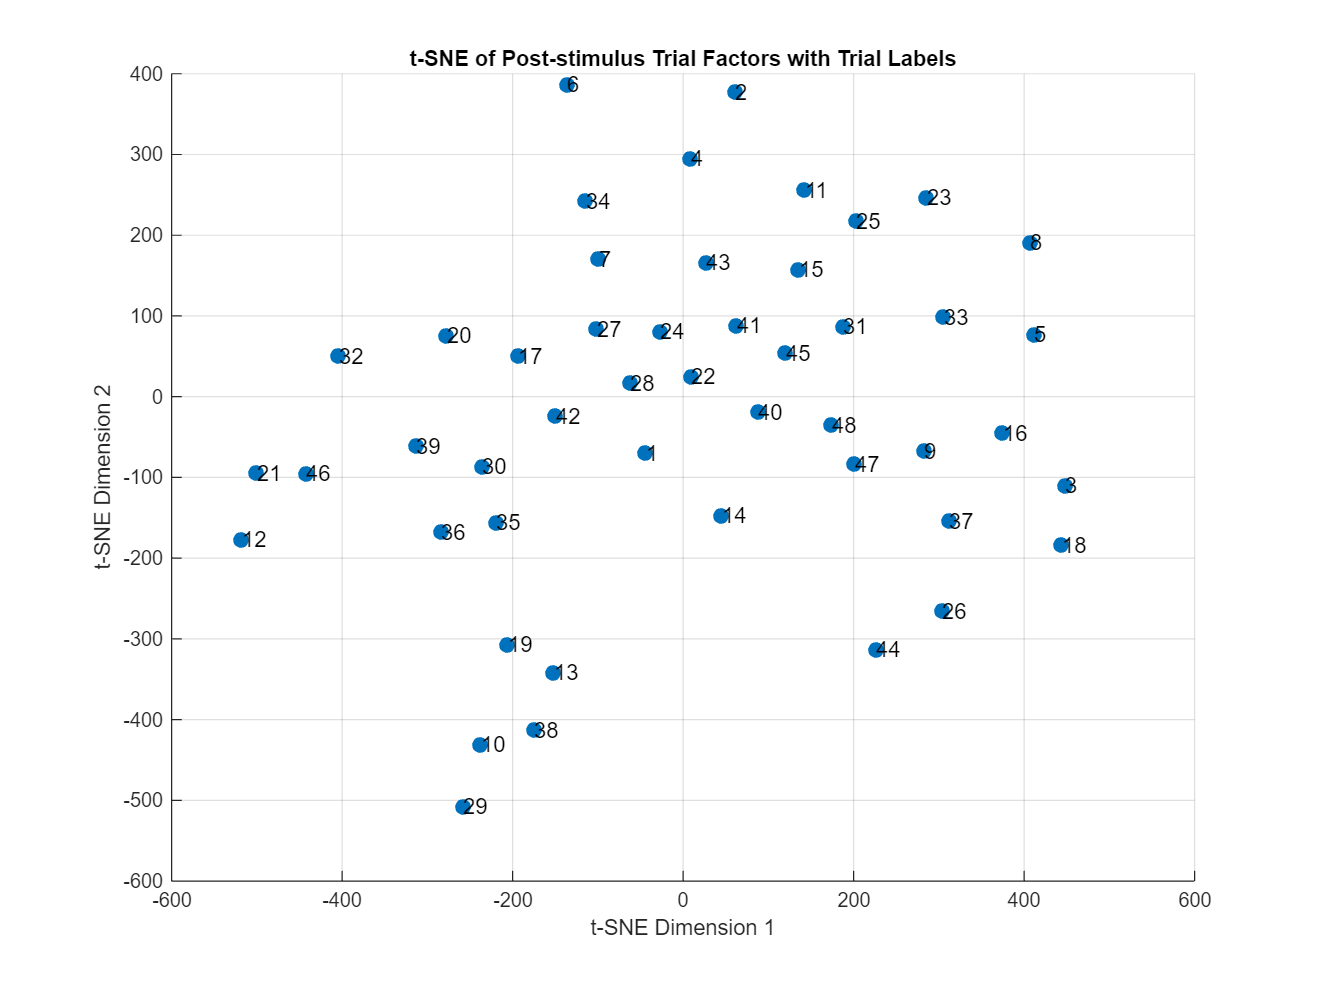


figure('Position', [100, 100, 800, 600]);
scatter(Y_post_trial(:,1), Y_post_trial(:,2), 50, 'filled');
title('t-SNE of Post-stimulus Trial Factors with Trial Labels');
xlabel('t-SNE Dimension 1'); 
ylabel('t-SNE Dimension 2');
grid on;
% Add trial numbers as text labels (may be crowded with many trials)
for i = 1:size(Y_post_trial, 1)
    text(Y_post_trial(i,1), Y_post_trial(i,2), num2str(i), 'FontSize', 10);
end

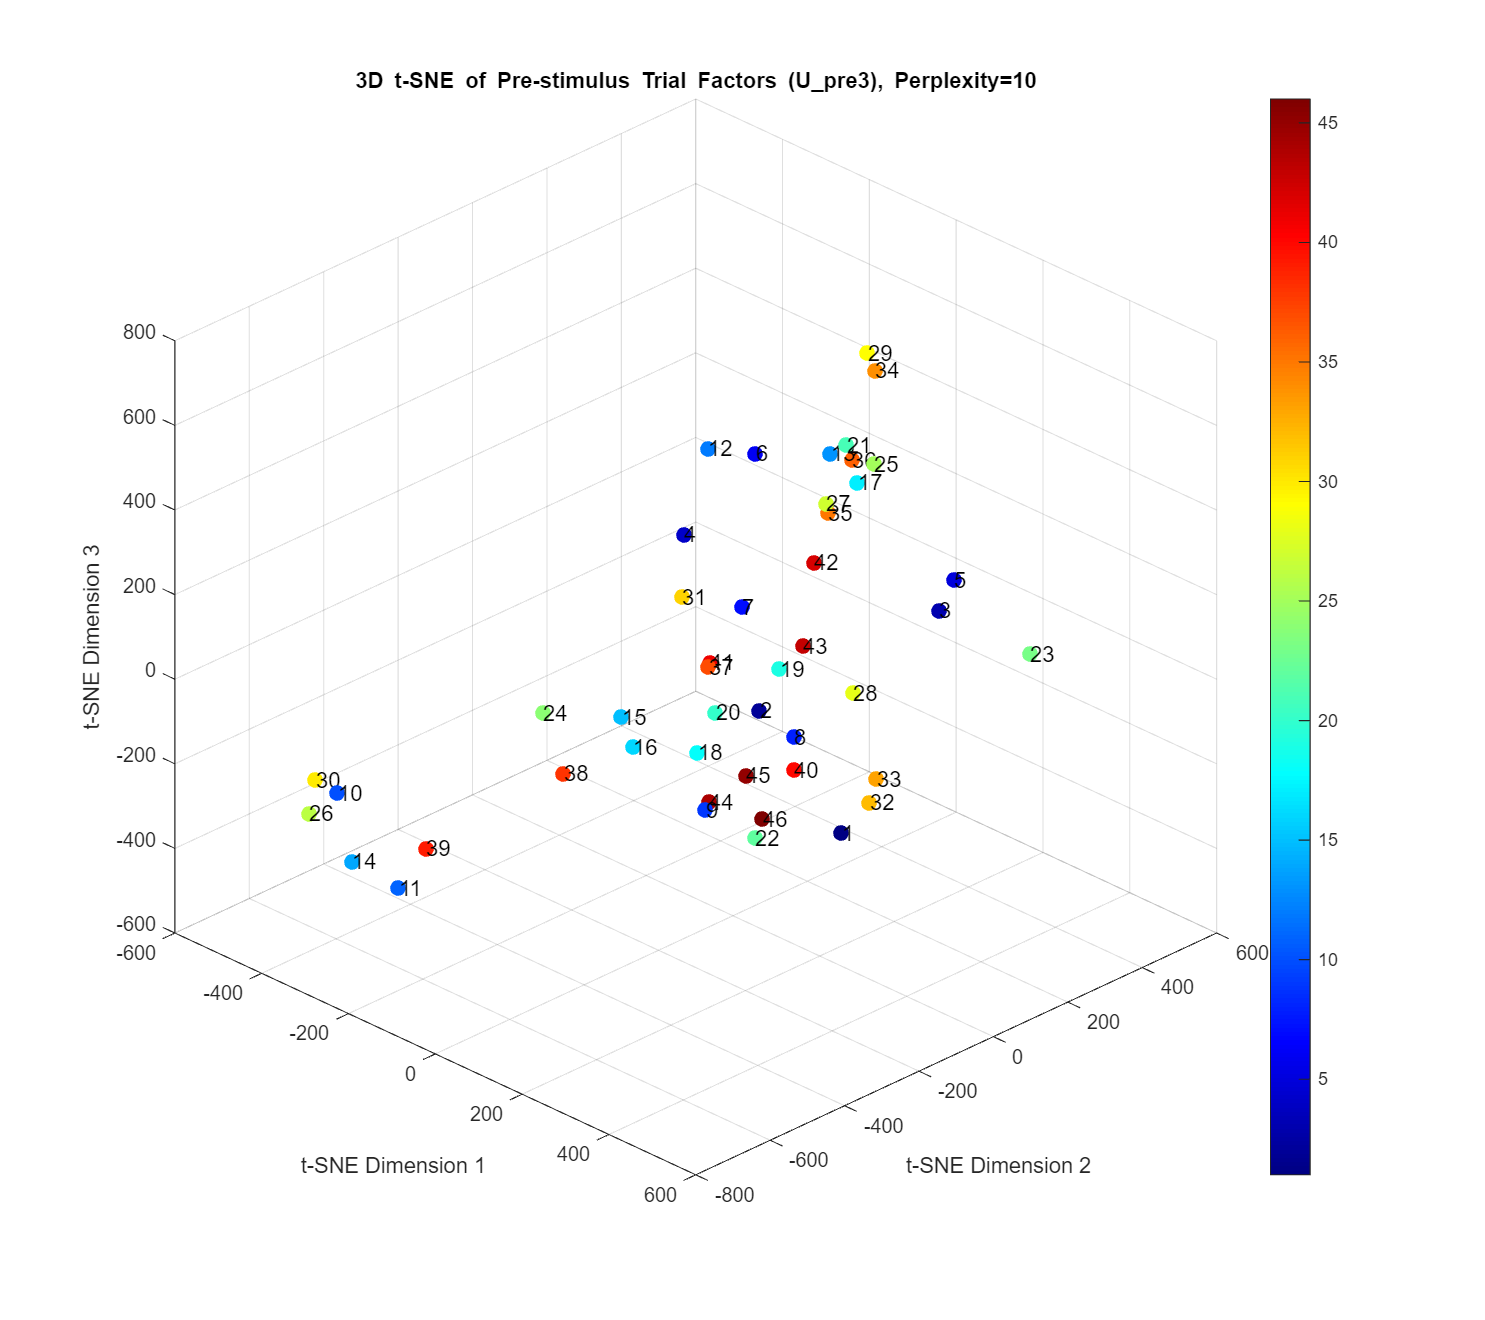


% t-SNE clustering on trial factors U_pre{3} and U_post{3} with 3D visualization

% Parameters for t-SNE
% perplexity = 10;  % Set perplexity to 60 as requested
num_dims = 3;     % 3D visualization

% t-SNE for pre-stimulus trial factors
% Transpose the matrix so each row represents a trial
trial_factors_pre = U_pre{3}';
Y_pre_trial = tsne(trial_factors_pre, 'Perplexity', min(perplexity, size(trial_factors_pre, 1)-1), 'NumDimensions', num_dims);

% t-SNE for post-stimulus trial factors
trial_factors_post = U_post{3}';
Y_post_trial = tsne(trial_factors_post, 'Perplexity', min(perplexity, size(trial_factors_post, 1)-1), 'NumDimensions', num_dims);

% 3D Plot for pre-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_pre_trial(:,1), Y_pre_trial(:,2), Y_pre_trial(:,3), 50, 1:size(Y_pre_trial,1), 'filled');
colormap(jet);
colorbar;
title(['3D t-SNE of Pre-stimulus Trial Factors (U\_pre{3}), Perplexity=' num2str(perplexity)]);
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_pre_trial, 1)
    text(Y_pre_trial(i,1), Y_pre_trial(i,2), Y_pre_trial(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

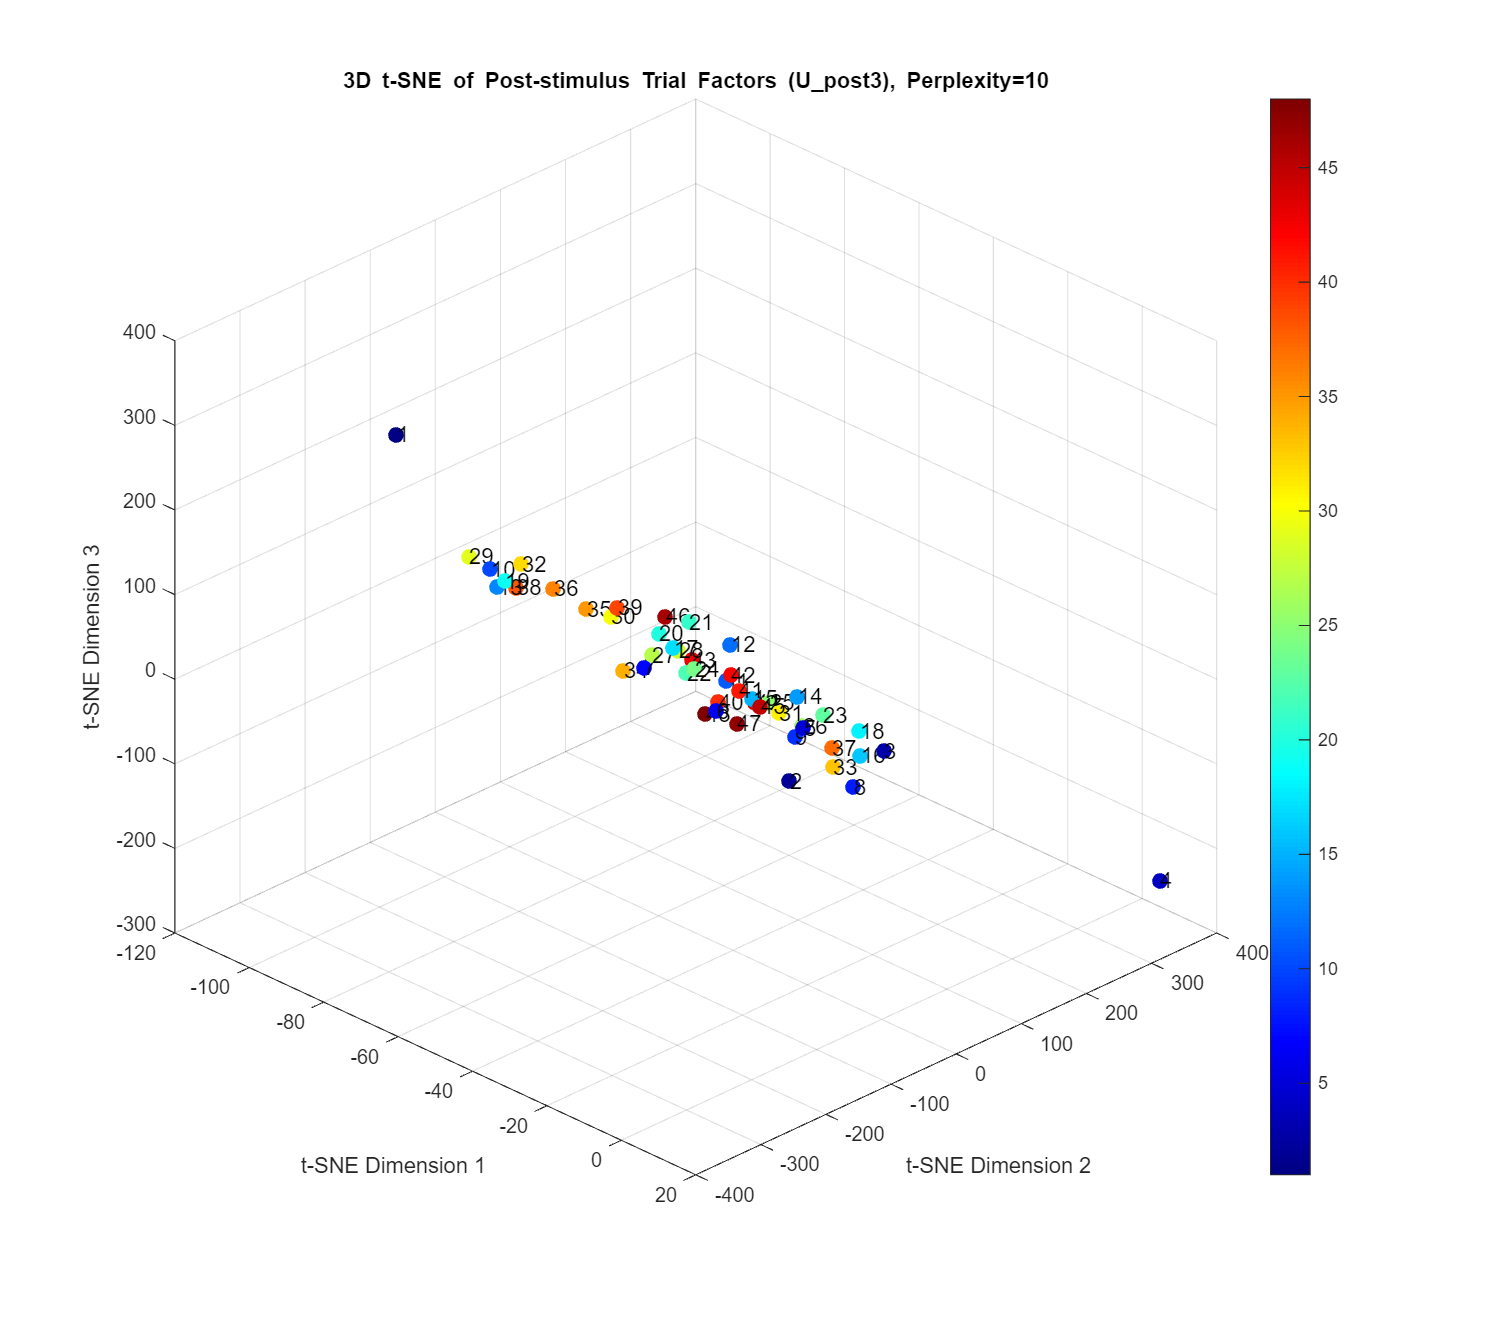


% 3D Plot for post-stimulus t-SNE results with trial labels
figure('Position', [100, 100, 900, 800]);
scatter3(Y_post_trial(:,1), Y_post_trial(:,2), Y_post_trial(:,3), 50, 1:size(Y_post_trial,1), 'filled');
colormap(jet);
colorbar;
title(['3D t-SNE of Post-stimulus Trial Factors (U\_post{3}), Perplexity=' num2str(perplexity)]);
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');
grid on;

% Add trial numbers as text labels
for i = 1:size(Y_post_trial, 1)
    text(Y_post_trial(i,1), Y_post_trial(i,2), Y_post_trial(i,3), num2str(i), 'FontSize', 10);
end

% Improve the view angle for better visualization
view(45, 30);

% Add ability to rotate the 3D plots
rotate3d on;

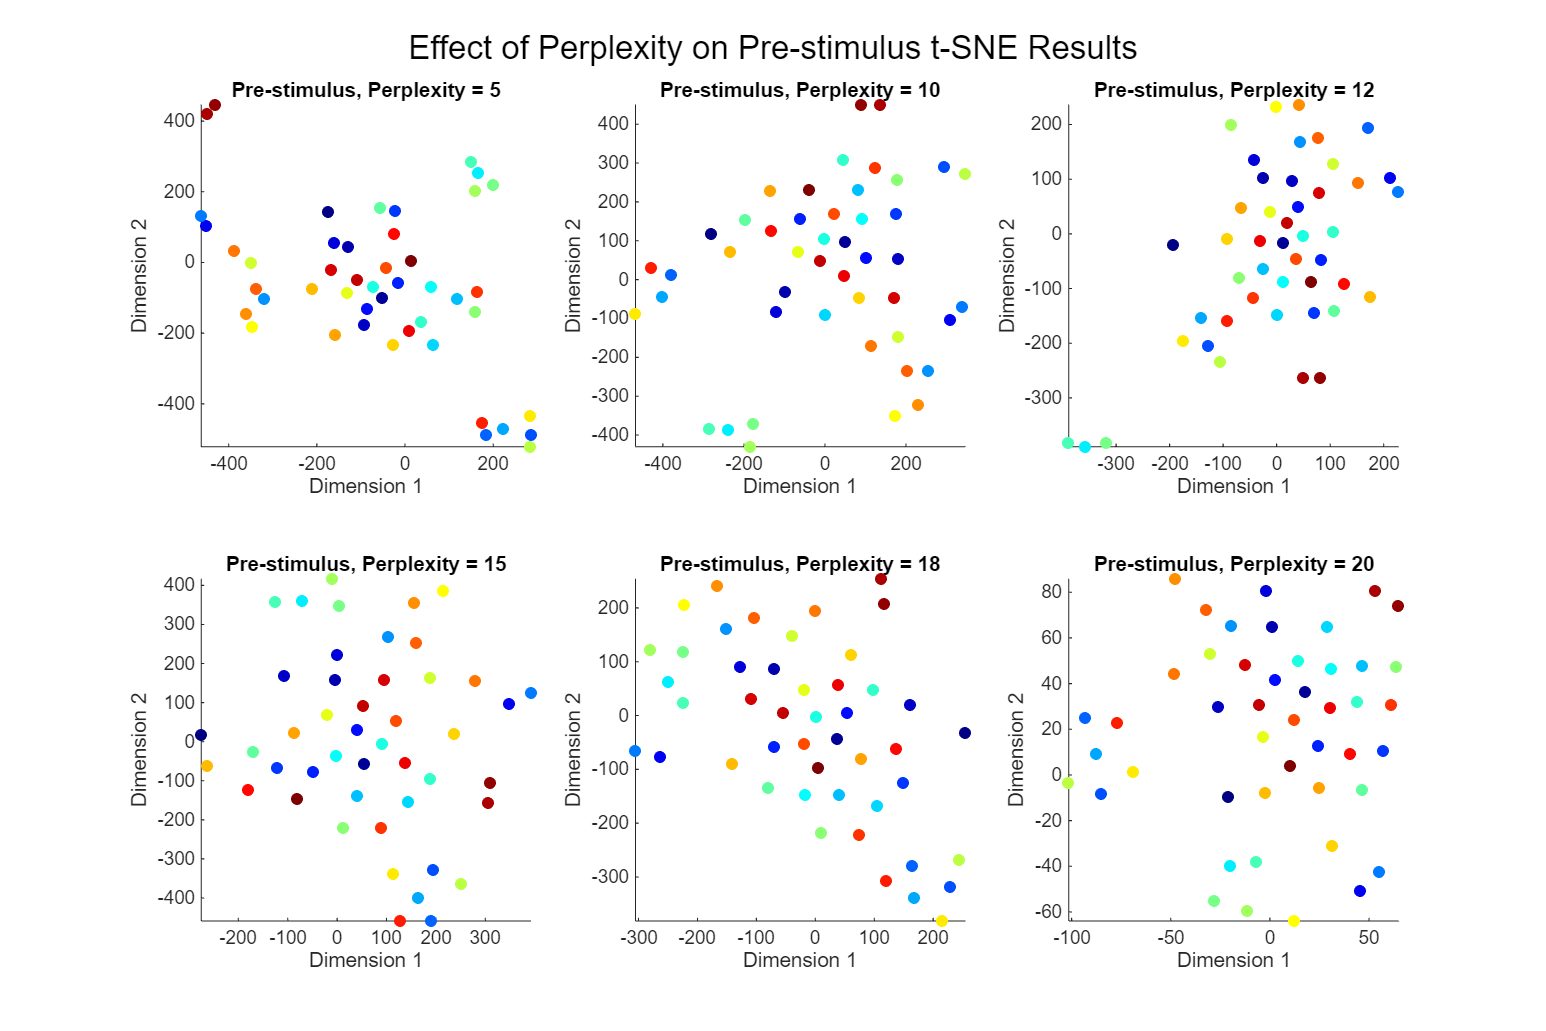

% Systematic approach to selecting perplexity
perplexity_values = [5, 10,12, 15, 18, 20];
num_dims = 2;  % Using 2D for easier comparison

% Preallocate cell arrays to store results
Y_pre_results_trial = cell(length(perplexity_values), 1);
Y_post_results_trial = cell(length(perplexity_values), 1);

% Run t-SNE with different perplexity values
for i = 1:length(perplexity_values)
    perp = perplexity_values(i);
    effective_perp_trial = min(perp, size(trial_factors_pre, 1)-1);
    
    % Pre-stimulus
    Y_pre_results_trial{i} = tsne(trial_factors_pre, 'Perplexity', effective_perp_trial, 'NumDimensions', num_dims);
    
    % Post-stimulus
    Y_post_results_trial{i} = tsne(trial_factors_post, 'Perplexity', effective_perp_trial, 'NumDimensions', num_dims);
end

% Create a grid of plots for pre-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_pre_results_trial{i}(:,1), Y_pre_results_trial{i}(:,2), 30, 1:size(Y_pre_results_trial{i},1), 'filled');
    title(['Pre-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Pre-stimulus t-SNE Results');

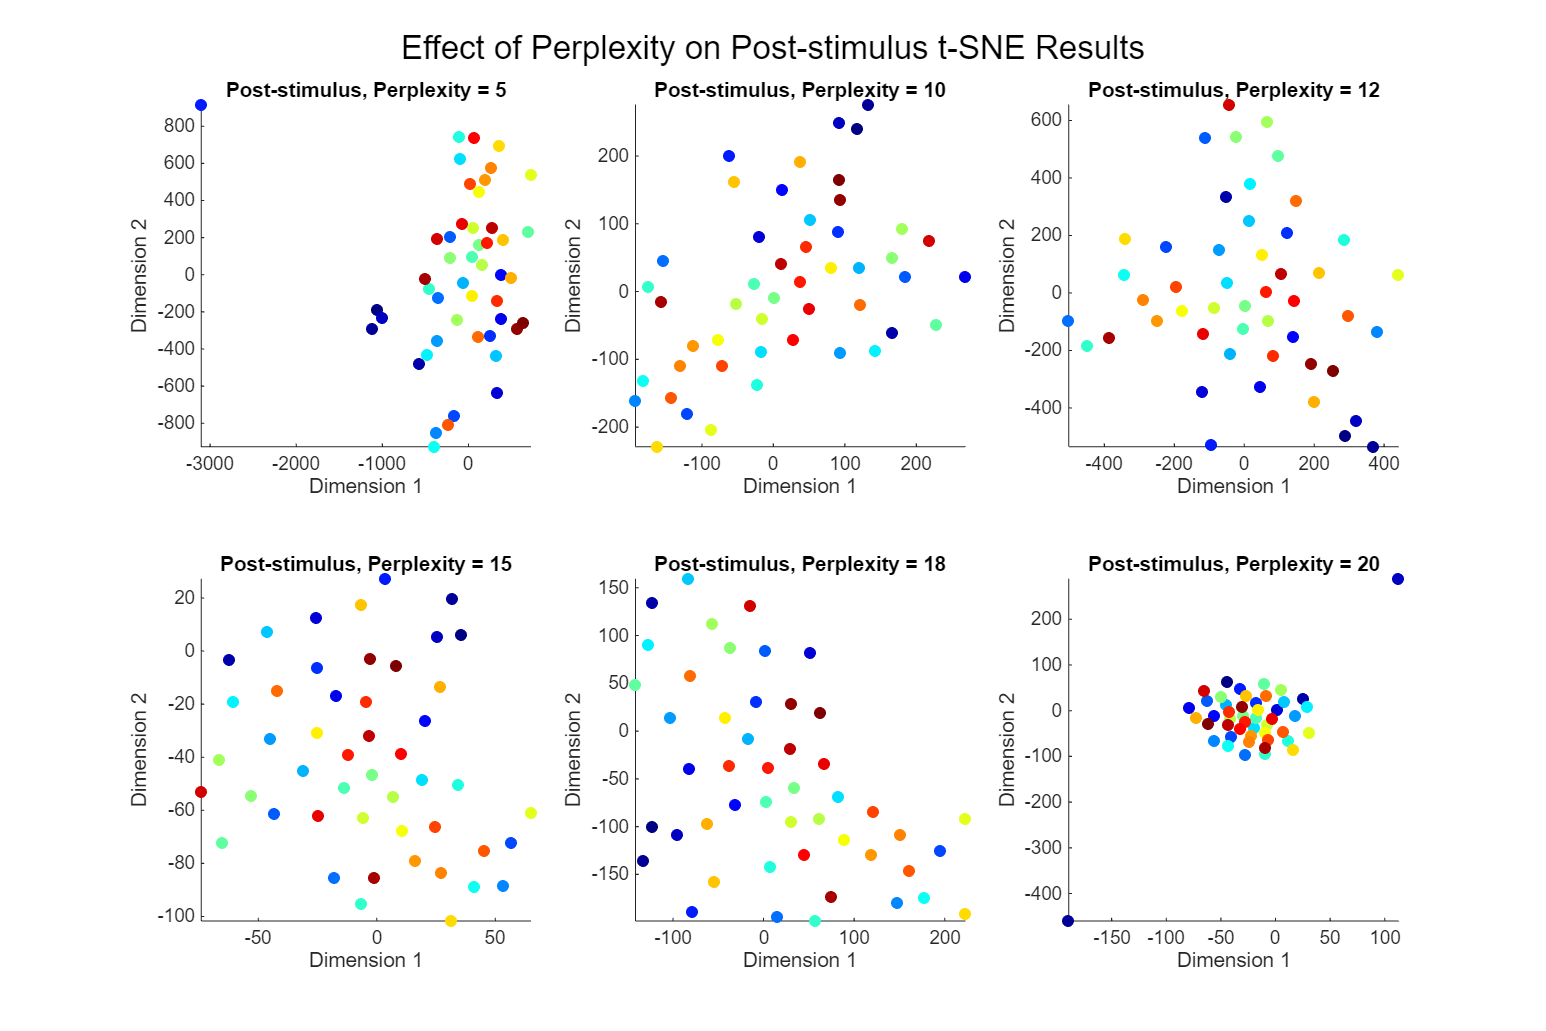


% Create a grid of plots for post-stimulus results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_post_results_trial{i}(:,1), Y_post_results_trial{i}(:,2), 30, 1:size(Y_post_results_trial{i},1), 'filled');
    title(['Post-stimulus, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
end
sgtitle('Effect of Perplexity on Post-stimulus t-SNE Results');

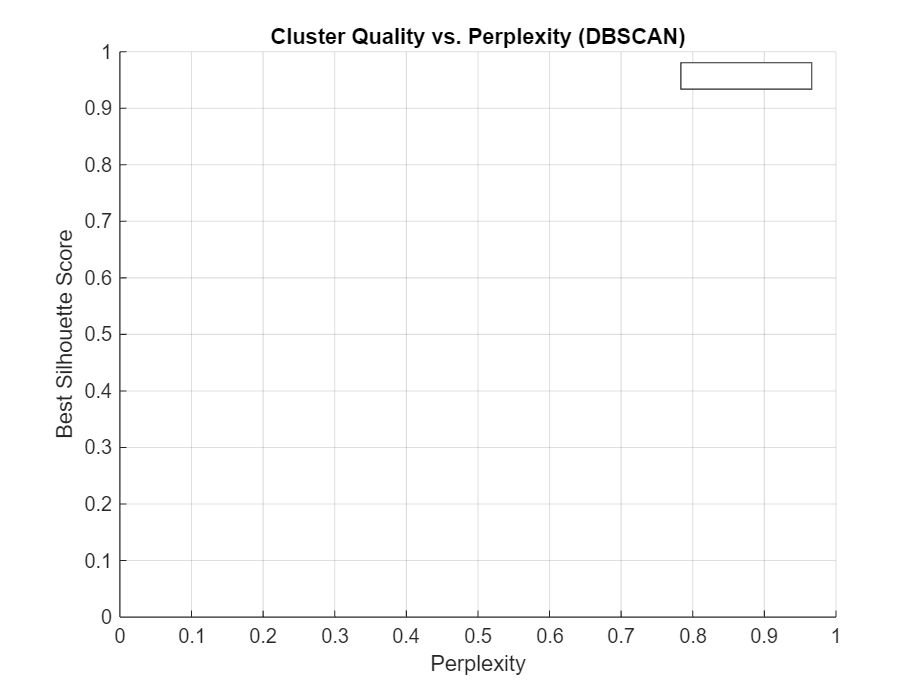

% Alternative cluster quality evaluation using DBSCAN
epsilon_values = [0.5, 1, 2]; % Multiple epsilon values to try
best_silhouette_pre = zeros(length(perplexity_values), 1);
best_silhouette_post = zeros(length(perplexity_values), 1);

for i = 1:length(perplexity_values)
    max_sil_pre = -1;
    max_sil_post = -1;
    
    % Try different epsilon values for DBSCAN
    for eps_val = epsilon_values
        % Pre-stimulus
        try
            % Normalize data before clustering
            data_pre = Y_pre_results_trial{i};
            data_pre = (data_pre - mean(data_pre)) ./ std(data_pre);
            
            idx_pre = dbscan(data_pre, eps_val, 5);
            % Only calculate silhouette if we have more than one cluster 
            % and no noise points (labeled as -1)
            if length(unique(idx_pre)) > 1 && ~any(idx_pre == -1)
                sil_pre = mean(silhouette(data_pre, idx_pre));
                max_sil_pre = max(max_sil_pre, sil_pre);
            end
        catch
            % Skip this epsilon value if an error occurs
        end
        
        % Post-stimulus
        try
            data_post = Y_post_results_trial{i};
            data_post = (data_post - mean(data_post)) ./ std(data_post);
            
            idx_post = dbscan(data_post, eps_val, 5);
            if length(unique(idx_post)) > 1 && ~any(idx_post == -1)
                sil_post = mean(silhouette(data_post, idx_post));
                max_sil_post = max(max_sil_post, sil_post);
            end
        catch
            % Skip this epsilon value if an error occurs
        end
    end
    
    best_silhouette_pre(i) = max_sil_pre;
    best_silhouette_post(i) = max_sil_post;
end

% Plot best silhouette scores
figure;
valid_pre = best_silhouette_pre > 0;
valid_post = best_silhouette_post > 0;

plot(perplexity_values(valid_pre), best_silhouette_pre(valid_pre), 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values(valid_post), best_silhouette_post(valid_post), 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Best Silhouette Score');
title('Cluster Quality vs. Perplexity (DBSCAN)');
legend('Location', 'best');
grid on;

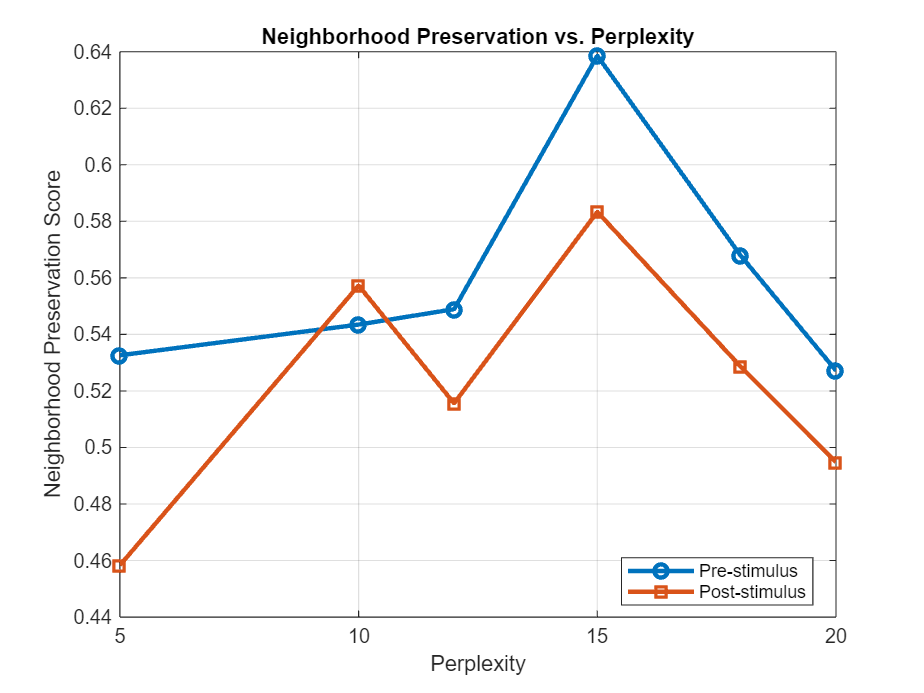

% A simpler approach: evaluate local neighborhood preservation
k_neighbors = 8; % Number of neighbors to consider
% Calculate neighborhood preservation for each perplexity
neighborhood_scores_pre = zeros(length(perplexity_values), 1);
neighborhood_scores_post = zeros(length(perplexity_values), 1);




for i = 1:length(perplexity_values)
    neighborhood_scores_pre(i) = calculate_neighborhood_preservation(trial_factors_pre, Y_pre_results_trial{i}, k_neighbors);
    neighborhood_scores_post(i) = calculate_neighborhood_preservation(trial_factors_post, Y_post_results_trial{i}, k_neighbors);
end

% Plot neighborhood preservation scores
figure;
plot(perplexity_values, neighborhood_scores_pre, 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values, neighborhood_scores_post, 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Neighborhood Preservation Score');
title('Neighborhood Preservation vs. Perplexity');
legend('Location', 'best');
grid on;

Testing n_neighbors=15, min_dist=0.10 (1/

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan



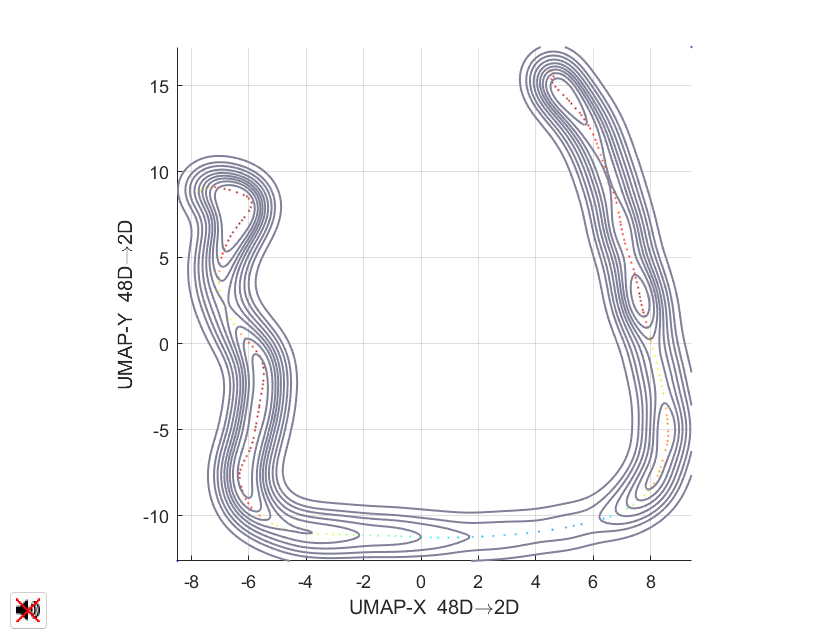


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0312 0.0425 0.0513 0.0588 0.0650 0.0709 0.0772 0.0864 0.0980 0.1296]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


UMAP reduction finished (cost 0.93 secs)
 Finished basic (ub) reduction


UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan



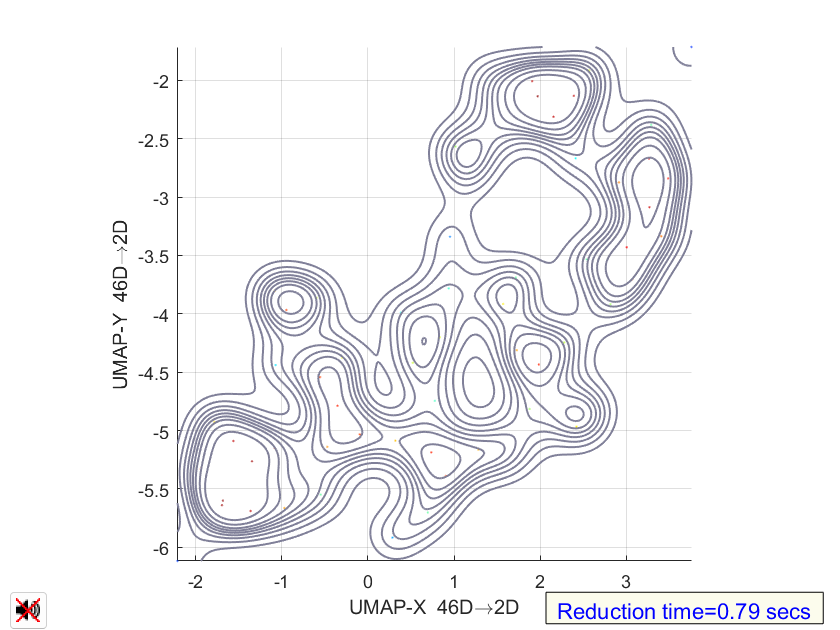


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0301 0.0429 0.0525 0.0614 0.0684 0.0749 0.0822 0.0910 0.1018 0.1538]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


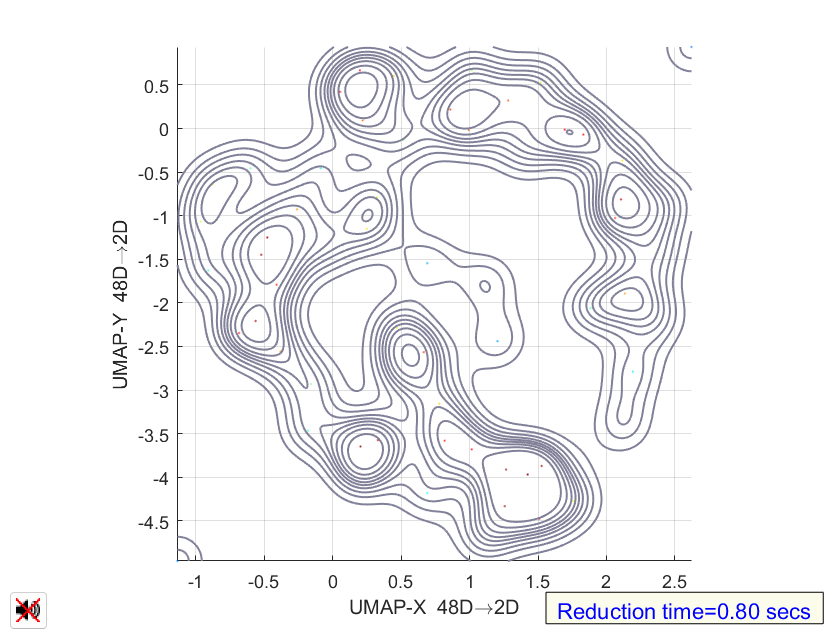

UMAP reduction finished (cost 0.94 secs)
 Finished basic (ub) reduction


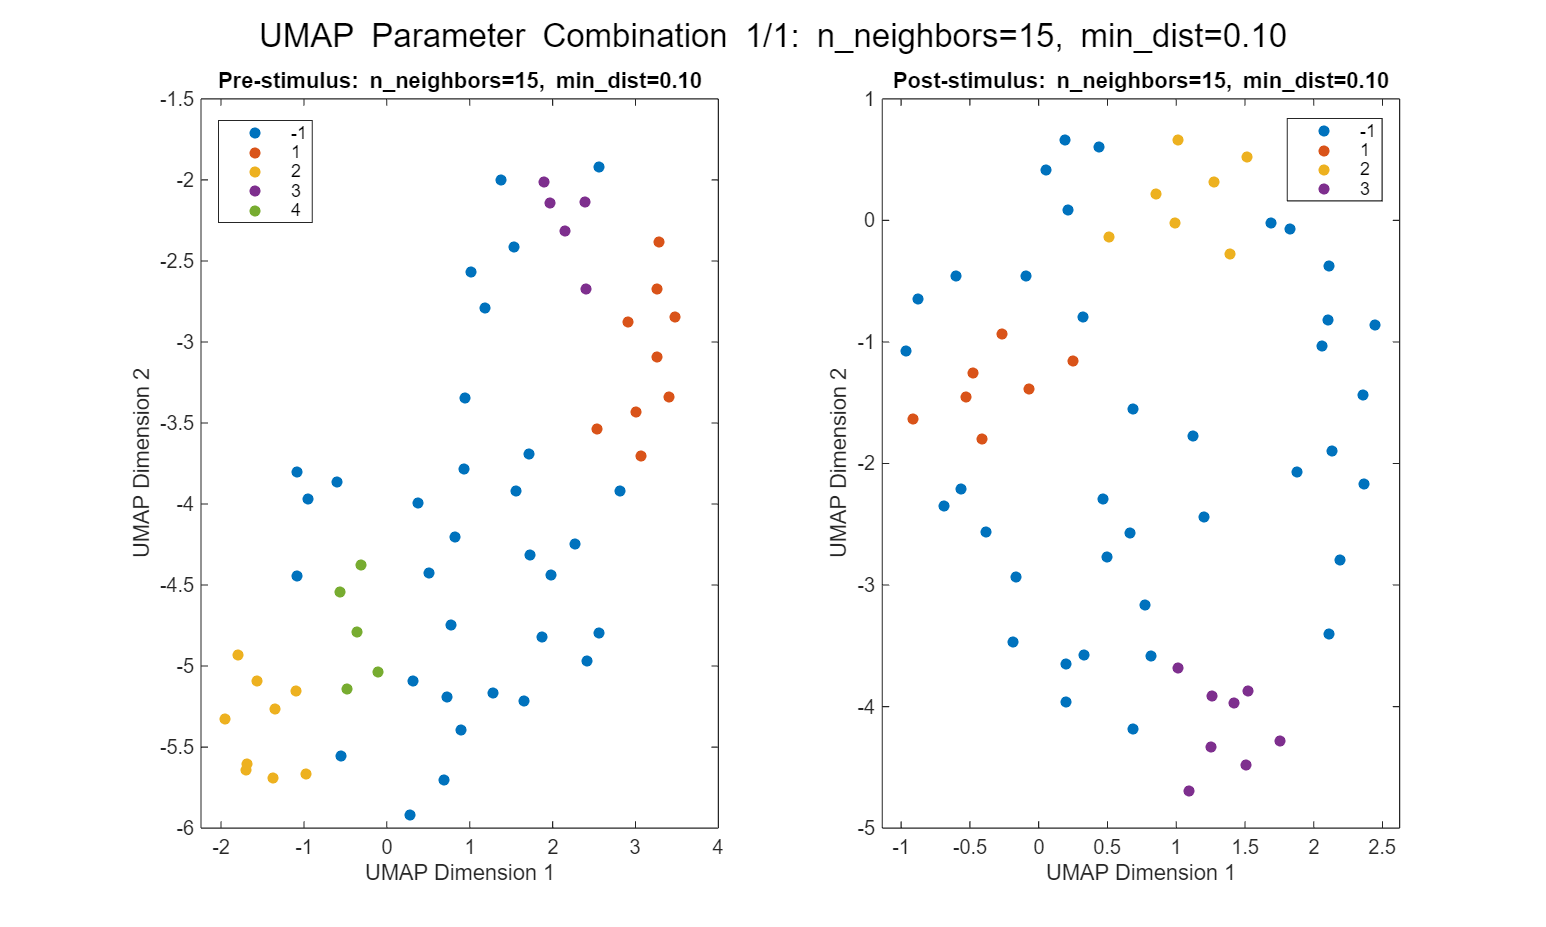

% Trial factor analysis using UMAP
% First, make sure you have the UMAP MATLAB package installed
% You can install it via: 
% https://www.mathworks.com/matlabcentral/fileexchange/71902-uniform-manifold-approximation-and-projection-umap

% Define parameter combinations to test
% n_neighbors_values = [3, 8, 15, 20];
% min_dist_values = [0.1, 0.5, 0.8]; % Changed 1.0 to 0.8 to avoid potential boundary issues
n_neighbors_values = [15];
min_dist_values = [0.1]; %
% Number of combinations
num_combinations = length(n_neighbors_values) * length(min_dist_values);

% Create structure to store results
results = struct('n_neighbors', {}, 'min_dist', {}, ...
                'umap_pre', {}, 'umap_post', {}, ...
                'pre_clusters', {}, 'post_clusters', {}, ...
                'status', {});

% Set consistent random seed for reproducibility
rng(42);

% Prepare figure for visualization
figure('Position', [100, 100, 1200, 800]);

% Counter for subplot positions
combo_idx = 1;

% Loop through all parameter combinations
for i = 1:length(n_neighbors_values)
    for j = 1:length(min_dist_values)
        % Current parameter set
        curr_n_neighbors = n_neighbors_values(i);
        curr_min_dist = min_dist_values(j);
        
        % Initialize current result entry
        curr_result = struct('n_neighbors', curr_n_neighbors, ...
                           'min_dist', curr_min_dist, ...
                           'umap_pre', [], 'umap_post', [], ...
                           'pre_clusters', [], 'post_clusters', [], ...
                           'status', 'pending');
        
        % Display current parameter combination
        fprintf('Testing n_neighbors=%d, min_dist=%.2f (%d/%d)\n', ...
                curr_n_neighbors, curr_min_dist, num_combinations);
        
        % Try running UMAP with current parameters
        try
            % Run UMAP on pre-condition trial factors
            [umap_pre, umap_params] = run_umap(U_pre{3}, 'n_neighbors', curr_n_neighbors, ...
                                             'min_dist', curr_min_dist, ...
                                             'n_components', 2, ...
                                             'seed', 42);
            
            % Run UMAP on post-condition trial factors
            [umap_post, ~] = run_umap(U_post{3}, 'n_neighbors', curr_n_neighbors, ...
                                    'min_dist', curr_min_dist, ...
                                    'n_components', 2, ...
                                    'seed', 42);
            
            % Store UMAP results
            curr_result.umap_pre = umap_pre;
            curr_result.umap_post = umap_post;
            
            % Apply DBSCAN clustering
            epsilon = 0.5;  % You might want to adjust this for each parameter set
            minPts = 5;
            
            curr_result.pre_clusters = dbscan(umap_pre, epsilon, minPts);
            curr_result.post_clusters = dbscan(umap_post, epsilon, minPts);
            
            % Mark as successful
            curr_result.status = 'success';
            
           % Create a new figure for this parameter combination
            fig = figure('Position', [100, 100, 1000, 600]);
            
            % Pre-stimulus plot
            subplot(1, 2, 1);
            gscatter(umap_pre(:,1), umap_pre(:,2), curr_result.pre_clusters);
            title(sprintf('Pre-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Post-stimulus plot
            subplot(1, 2, 2);
            gscatter(umap_post(:,1), umap_post(:,2), curr_result.post_clusters);
            title(sprintf('Post-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            
            % Add overall title
            sgtitle(sprintf('UMAP Parameter Combination %d/%d: n\\_neighbors=%d, min\\_dist=%.2f', ...
                combo_idx, num_combinations, curr_n_neighbors, curr_min_dist));
            
            % % Save the figure
            % fig_filename = sprintf('umap_params_n%d_d%.2f.png', curr_n_neighbors, curr_min_dist);
            % saveas(fig, fig_filename);
            % 
            % % Optional: close the figure if you don't want too many open at once
            % close(fig);
            
        catch e
            % Handle errors
            fprintf('Error with n_neighbors=%d, min_dist=%.2f: %s\n', ...
                    curr_n_neighbors, curr_min_dist, e.message);
            curr_result.status = sprintf('error: %s', e.message);
        end
        
        % Store current result
        results(end+1) = curr_result;
        
        % Increment combination counter
        combo_idx = combo_idx + 1;
    end
end


% Save all results to a MAT file
save('umap_parameter_exploration.mat', 'results');

% Display summary
fprintf('\nParameter Testing Summary:\n');


Parameter Testing Summary:


fprintf('------------------------\n');

------------------------


for i = 1:length(results)
    fprintf('n_neighbors=%d, min_dist=%.2f: %s\n', ...
            results(i).n_neighbors, results(i).min_dist, results(i).status);
end

n_neighbors=15, min_dist=0.10: success


% Function to calculate neighborhood preservation

function score = calculate_neighborhood_preservation(orig_data, embedded_data, k)
    % Get the k nearest neighbors in original space
    [~, orig_idx] = pdist2(orig_data, orig_data, 'euclidean', 'Smallest', k+1);
    orig_idx = orig_idx(2:end, :)'; % Remove self and transpose
    
    % Get the k nearest neighbors in embedded space
    [~, emb_idx] = pdist2(embedded_data, embedded_data, 'euclidean', 'Smallest', k+1);
    emb_idx = emb_idx(2:end, :)'; % Remove self and transpose
    
    % Calculate overlap between neighborhoods
    overlap = 0;
    for i = 1:size(orig_data, 1)
        overlap = overlap + length(intersect(orig_idx(i,:), emb_idx(i,:)));
    end
    
    % Return average percentage of preserved neighbors
    score = overlap / (k * size(orig_data, 1));
end